# Setup

addpath('../LabFiles/Functions/')
addpath('../LabFiles/Images-m/')

# K-Means

K = 4;               % number of clusters used
L = 10;              % number of iterations
seed = 14;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

orange = imread('orange.jpg');
orange = imresize(orange, scale_factor);
Iback = orange;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
orange = imfilter(orange, h);

tic
[ segm, ~ ] = kmeans_segm(orange, K, L, seed);
toc

Elapsed time is 0.132738 seconds.


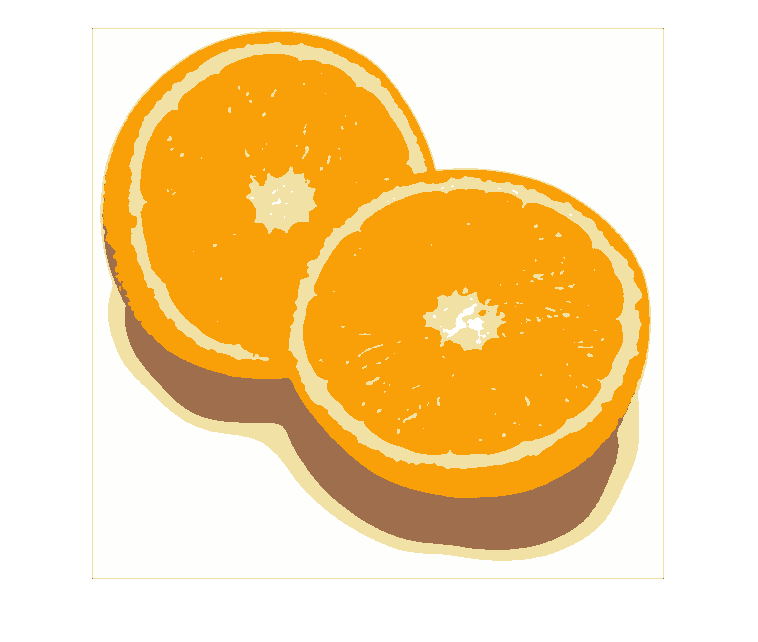

Inew = mean_segments(Iback, segm);
imshow(Inew);

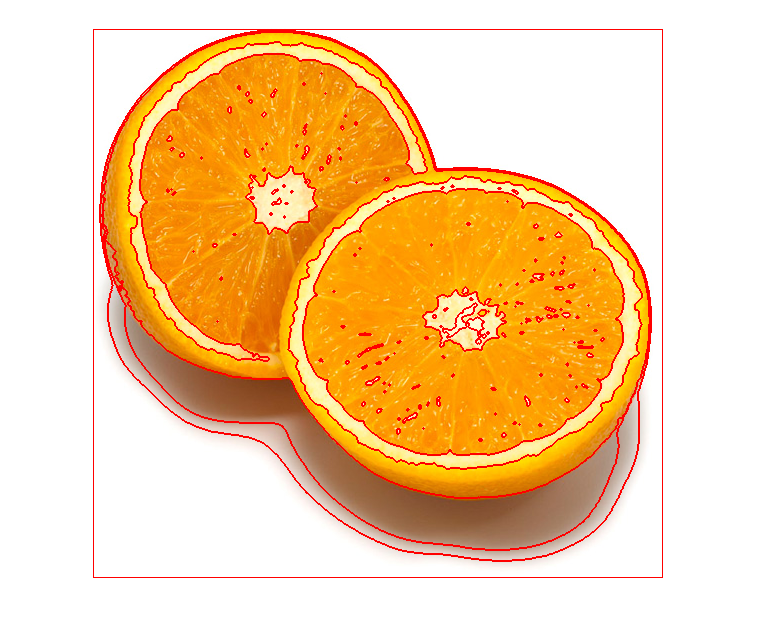

orange = overlay_bounds(Iback, segm);
imshow(orange);

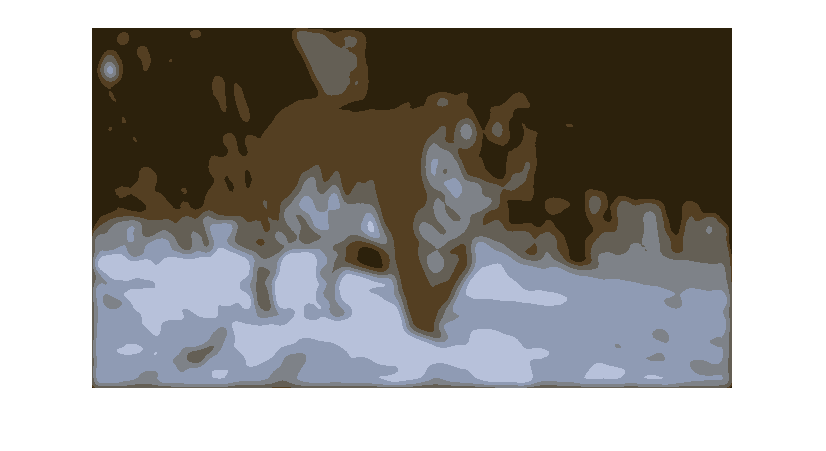


K = 6;               % number of clusters used
L = 20;              % number of iterations
seed = 14;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 5.0;   % image preblurring scale

orange = imread('tiger2.jpg');
orange = imresize(orange, scale_factor);
Iback = orange;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
orange = imfilter(orange, h);

[ segm, centers ] = kmeans_segm(orange, K, L, seed);

Inew = mean_segments(Iback, segm);
imshow(Inew);

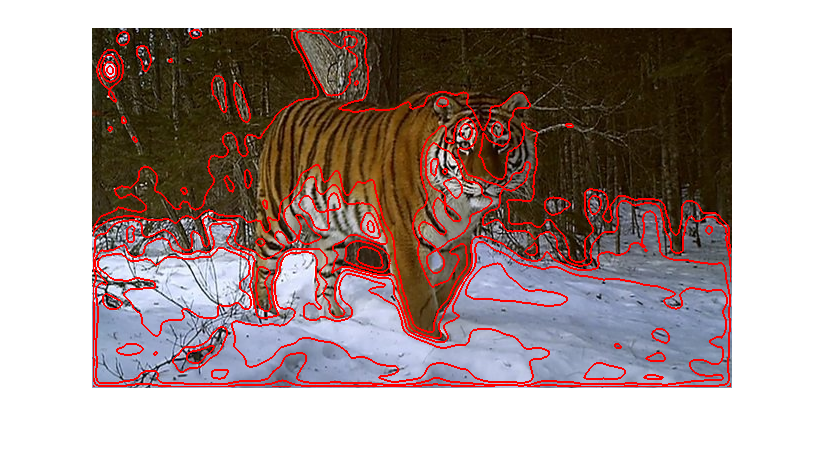

orange = overlay_bounds(Iback, segm);
imshow(orange);

# Mean Shift

scale_factor = 0.9;       % image downscale factor
spatial_bandwidth = 12.0;  % spatial bandwidth
colour_bandwidth = 5.0;   % colour bandwidth
num_iterations = 60;      % number of mean-shift iterations
image_sigma = 5.0;        % image preblurring scale

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);

Find colour channels with K-means...
Elapsed time is 0.184828 seconds.
Elapsed time is 0.311516 seconds.
Search for high density points...
Elapsed time is 0.363408 seconds.
Elapsed time is 0.394503 seconds.
Elapsed time is 0.422836 seconds.
Elapsed time is 0.453417 seconds.
Elapsed time is 0.489862 seconds.
Elapsed time is 0.517103 seconds.
Elapsed time is 0.565778 seconds.
Elapsed time is 0.595066 seconds.
Elapsed time is 0.619465 seconds.
Elapsed time is 0.646008 seconds.
Elapsed time is 0.673749 seconds.
Elapsed time is 0.703160 seconds.
Elapsed time is 0.727884 seconds.
Elapsed time is 0.758614 seconds.
Elapsed time is 0.787300 seconds.
Elapsed time is 0.815323 seconds.
Elapsed time is 0.840966 seconds.
Elapsed time is 0.867235 seconds.
Elapsed time is 0.895636 seconds.
Elapsed time is 0.927335 seconds.
Elapsed time is 0.954118 seconds.
Elapsed time is 0.980388 seconds.
Elapsed time is 1.007257 seconds.
Elapsed time is 1.032266 seconds.
Elapsed time is 1.056303 seconds.
Elapsed tim

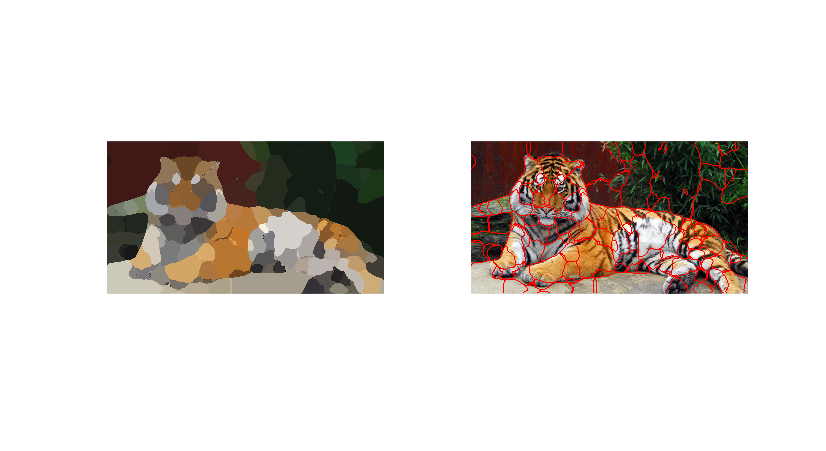

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

scale_factor = 0.9;       % image downscale factor
spatial_bandwidth = 7.0;  % spatial bandwidth
colour_bandwidth = 3.5;   % colour bandwidth
num_iterations = 60;      % number of mean-shift iterations
image_sigma = 3.0;        % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);

Find colour channels with K-means...
Elapsed time is 0.283314 seconds.
Elapsed time is 0.492642 seconds.
Search for high density points...
Elapsed time is 0.570139 seconds.
Elapsed time is 0.606134 seconds.
Elapsed time is 0.660311 seconds.
Elapsed time is 0.699214 seconds.
Elapsed time is 0.750478 seconds.
Elapsed time is 0.812027 seconds.
Elapsed time is 0.889737 seconds.
Elapsed time is 0.933421 seconds.
Elapsed time is 0.983131 seconds.
Elapsed time is 1.025448 seconds.
Elapsed time is 1.077617 seconds.
Elapsed time is 1.115269 seconds.
Elapsed time is 1.169629 seconds.
Elapsed time is 1.209063 seconds.
Elapsed time is 1.265317 seconds.
Elapsed time is 1.304291 seconds.
Elapsed time is 1.365274 seconds.
Elapsed time is 1.405491 seconds.
Elapsed time is 1.461498 seconds.
Elapsed time is 1.502960 seconds.
Elapsed time is 1.556061 seconds.
Elapsed time is 1.598724 seconds.
Elapsed time is 1.658633 seconds.
Elapsed time is 1.698307 seconds.
Elapsed time is 1.749897 seconds.
Elapsed tim

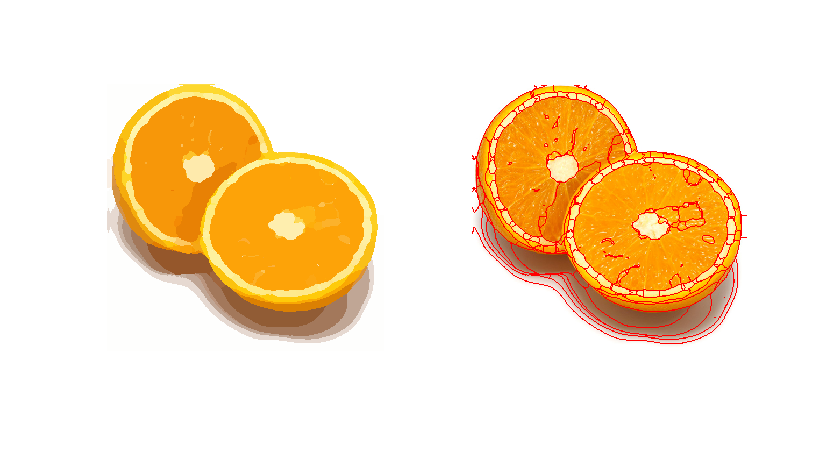

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

scale_factor = 0.9;       % image downscale factor
spatial_bandwidth = 7.0;  % spatial bandwidth
colour_bandwidth = 7.0;   % colour bandwidth
num_iterations = 60;      % number of mean-shift iterations
image_sigma = 8.0;        % image preblurring scale

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);

Find colour channels with K-means...
Elapsed time is 0.199007 seconds.
Elapsed time is 0.324480 seconds.
Search for high density points...
Elapsed time is 0.372349 seconds.
Elapsed time is 0.401939 seconds.
Elapsed time is 0.430504 seconds.
Elapsed time is 0.470004 seconds.
Elapsed time is 0.500051 seconds.
Elapsed time is 0.527223 seconds.
Elapsed time is 0.581762 seconds.
Elapsed time is 0.614274 seconds.
Elapsed time is 0.642429 seconds.
Elapsed time is 0.678574 seconds.
Elapsed time is 0.709459 seconds.
Elapsed time is 0.739478 seconds.
Elapsed time is 0.766057 seconds.
Elapsed time is 0.792591 seconds.
Elapsed time is 0.822984 seconds.
Elapsed time is 0.859015 seconds.
Elapsed time is 0.889710 seconds.
Elapsed time is 0.916761 seconds.
Elapsed time is 0.944292 seconds.
Elapsed time is 0.976270 seconds.
Elapsed time is 1.008618 seconds.
Elapsed time is 1.039592 seconds.
Elapsed time is 1.069220 seconds.
Elapsed time is 1.098294 seconds.
Elapsed time is 1.125159 seconds.
Elapsed tim

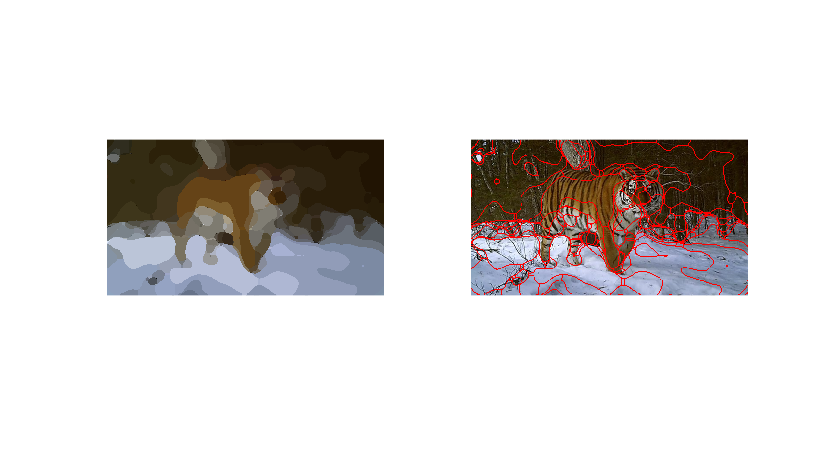

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

# Ncut

colour_bandwidth = 17.0; % color bandwidth
radius = 4;              % maximum neighbourhood distance
ncuts_thresh = 0.2;      % cutting threshold
min_area = 250;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 1.0;       % image preblurring scale

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Elapsed time is 0.265692 seconds.
Solve eigenvalue problems to find partitions...
Cutting ncut=0.003 sizes=(22658,14206)
Cutting ncut=0.014 sizes=(8329,14329)
Cutting ncut=0.019 sizes=(2792,5537)
Cutting ncut=0.029 sizes=(1282,1510)
Cutting ncut=0.037 sizes=(599,683)
Cutting ncut=0.070 sizes=(247,352)
Cutting ncut=0.096 sizes=(476,207)
Cutting ncut=0.025 sizes=(679,831)
Cutting ncut=0.182 sizes=(524,155)
Cutting ncut=0.104 sizes=(585,246)
Cutting ncut=0.021 sizes=(3148,2389)
Cutting ncut=0.040 sizes=(814,2334)
Cutting ncut=0.140 sizes=(336,478)
Cutting ncut=0.074 sizes=(185,151)
Cutting ncut=0.159 sizes=(171,307)
Cutting ncut=0.036 sizes=(1681,653)
Cutting ncut=0.060 sizes=(781,900)
Cutting ncut=0.148 sizes=(448,333)
Cutting ncut=0.162 sizes=(223,225)
Cutting ncut=0.175 sizes=(194,139)
Cutting ncut=0.133 sizes=(325,575)
Cutting ncut=0.225 sizes=(134,191)
Cutting ncut=0.269 sizes=(562,13)
Cutting ncut=0.036 sizes=(379,274)
Cutting ncut=0.079 sizes=(202,177)
Cu

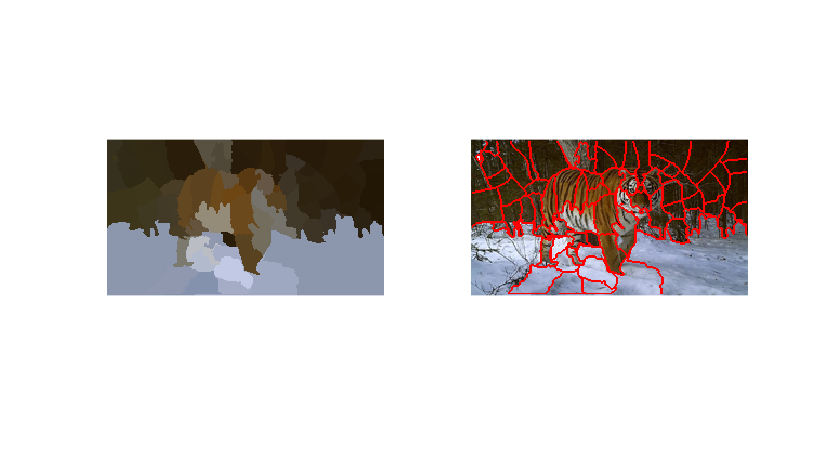

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/normcuts1.png')
%imwrite(I,'result/normcuts2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

colour_bandwidth = 17.0; % color bandwidth
radius = 4;              % maximum neighbourhood distance
ncuts_thresh = 0.1;      % cutting threshold
min_area = 250;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 1.0;       % image preblurring scale

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Elapsed time is 0.238965 seconds.
Solve eigenvalue problems to find partitions...


Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/normcuts1.png')
%imwrite(I,'result/normcuts2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

# Graph Cuts

scale_factor = 0.5;          % image downscale factor
area = [ 80, 110, 570, 300 ] % image region to train foreground with

area =     80   110   570   300


K = 15;                      % number of mixture components
alpha = 30.0;                 % maximum edge cost
sigma = 1.5;                % edge cost decay factor

I = imread('tiger3.jpg');
I = imresize(I, scale_factor);
Iback = I;
area = int16(area*scale_factor);
[ segm, prior ] = graphcut_segm(I, area, K, alpha, sigma);

Find Gaussian mixture models...
Elapsed time is 0.314869 seconds.
Find minimum cut...
number of iterations = 100. 

Elapsed time is 0.533018 seconds.
Find Gaussian mixture models...
Elapsed time is 0.905989 seconds.
Find minimum cut...
number of iterations = 75. 

Elapsed time is 1.083020 seconds.
Find Gaussian mixture models...
Elapsed time is 1.446955 seconds.
Find minimum cut...
number of iterations = 65. 

Elapsed time is 1.597333 seconds.


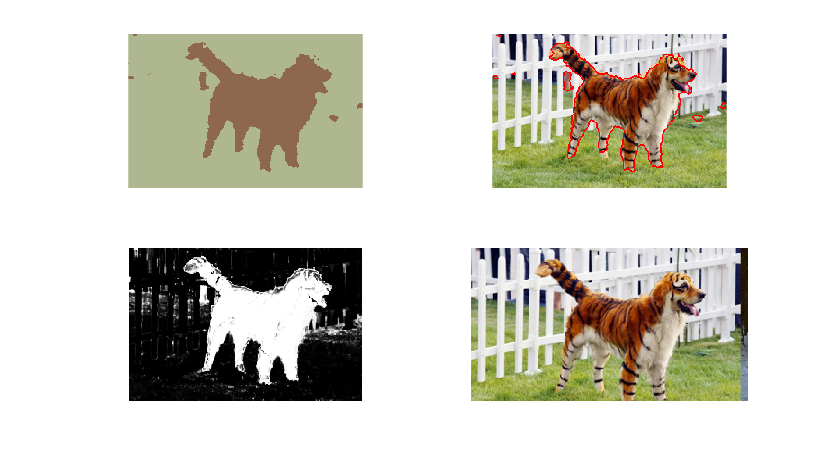


Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
hold on;
subplot(2,2,1); imshow(Inew);
subplot(2,2,2); imshow(I);
subplot(2,2,3); imshow(prior);
subplot(2,2,4); imshow(Iback);    
hold off;